- ***Проверка пары матриц A, Bна соответствие свойству полной управляемости, формирование матрицы управляемости объекта управления в исходном базисе ******U******. ***

A = [2 6; 1 0];
B = [4; 1];
C =[2 0];
U =[B A*B]

U =      4    14
     1     4


rank(U) == rank(A)

ans = logical
   1


***2. Проверка пары матриц A******, ******B на соответствие свойству полной управляемости, формирование матрицы управляемости объекта управления в исходном базисе ******U******. ***

charpoly(A)

ans =      1    -2    -6


***3. Переход от исходного описания объекта управления к управляемой канонической форме. ***

sys = ss(A,B,C, 0);
[b,a] = ss2tf(A,B,C,0)

b =      0     8    12


a =      1    -2    -6


A_y = [0 1; -a(3) -a(2)]

A_y =      0     1
     6     2


B_y = [0;1]

B_y =      0
     1


C_y = [b(3) b(2) 0]

C_y =     12     8     0


***4. Расчёт желаемого характеристического полинома замкнутой системы по заданным показателям качества (время переходного процесса t******п******, перерегулирование ******s******). ***

t_p = 2.2;
sigma = 0.06;
t_p1 = 2.9;
w = t_p1/t_p

w = 1.3182

Полученный полином:


$$a\left(s\right)=s^2 +1\ldotp 414\textrm{ws}+w^2$$


syms s
a = s^2+1.414*w*s+w^2;
sym2poly(a)

ans =     1.0000    1.8639    1.7376


a0 = w^2; 
a1 = 1.414*w;

***5. Формирование желаемой матрицы замкнутой системы F******k******. ***

Fk = [0 1; -a0 -a1]

Fk =          0    1.0000
   -1.7376   -1.8639


F_k = A_y- B_y*K_k

F_k =          0    1.0000
   -1.7376   -1.8639


***6. Нахождение матрицы преобразования ******P******, которая вычисляется как ******P******= ******U******k******U******-1******, где ******U******k******— матрица управляемости объекта управления в управляемой канонической форме; ******U****** — матрица управляемости исходного объекта управления. ***

Uk = [B_y A_y*B_y]

Uk =      0     1
     1     2


P = Uk*U^-1

P =    -0.5000    2.0000
    1.0000   -3.0000


***7. Вычисление коэффициентов обратных связей K******k******в управляемом каноническом виде. ***

K_kk = (A_y-Fk)

K_kk =          0         0
    7.7376    3.8639


K_k = [K_kk(2, 1) K_kk(2, 2)]

K_k =     7.7376    3.8639


***8. Нахождение матрицы линейных стационарных обратных связей K в исходном базисе***

K=K_k*P

K =    -0.0049    3.8835


***9. Проверка характеристического полинома замкнутой системы на соответствие желаемых показателей качества замкнутой системы. ***

syms lambda
sym2poly(det(lambda*eye(2)-(A-B*K)))

ans =     1.0000    1.8639    1.7376


sym2poly(det(lambda*eye(2)-Fk))

ans =     1.0000    1.8639    1.7376


lambda_12 = solve(det(lambda*eye(2)-Fk)==0, lambda);
lambda1 = sym2poly(lambda_12(1))

lambda1 = -0.9320 - 0.9322i

lambda2 = sym2poly(lambda_12(2))

lambda2 = -0.9320 + 0.9322i

t_p = 1/(-real(lambda1)) * log(1/0.05)

t_p = 3.2145

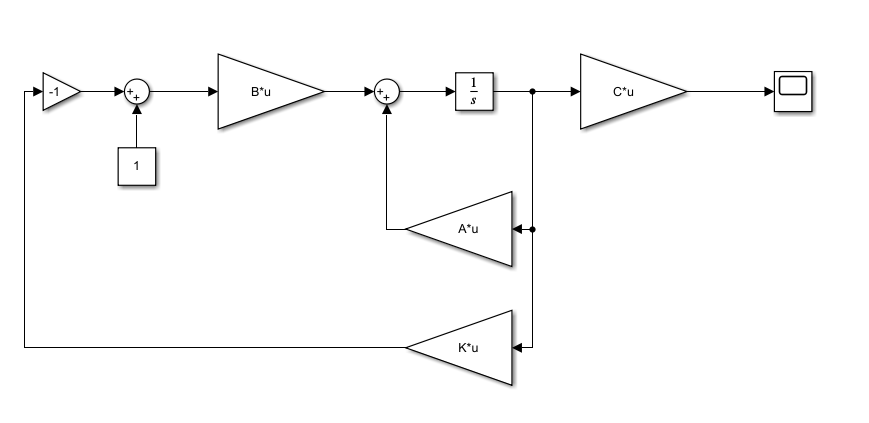

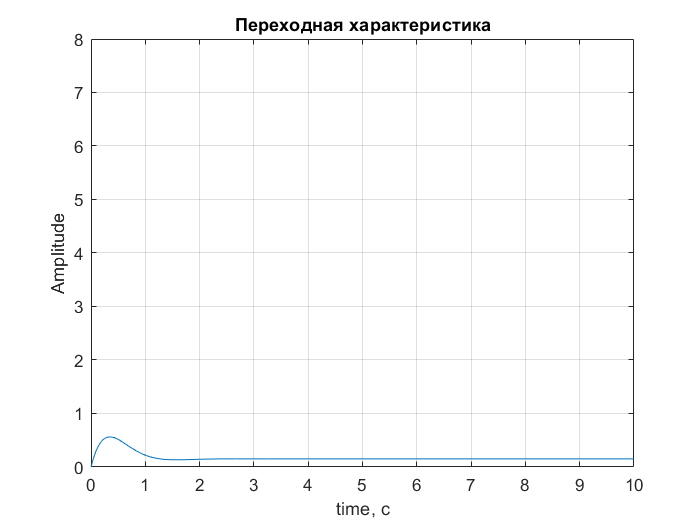

plot(out.ScopeData.time, out.ScopeData.signals.values)
xlim([0.00 10.00])
ylim([0.00 8.00])
grid on
title('Переходная характеристика')
xlabel('time, c')
ylabel('Amplitude')